# Nedkøling af brine

clc; clear all;

brine = importdata("NiceBrineData.txt");

CP = py.importlib.import_module("CoolProp.CoolProp");


ind = 10;

brine_Tefordamp = find(brine.textdata(1,2:end) == "Temperaturen efter fordamper")

brine_Tefordamp = 6

brine_Tffordamp = find(brine.textdata(1,2:end) == "Temperatur efter EPV")

brine_Tffordamp = 9

brine_Tbrine = find(brine.textdata(1,2:end) == "Brinetemperatur")

brine_Tbrine = 4


brine_Tffordamp = brine.data(ind:end-ind, brine_Tffordamp);
brine_Tefordamp = brine.data(ind:end-ind, brine_Tefordamp);
brine_Tbrine = brine.data(ind:end-ind, brine_Tbrine);


ind_plot = find(max(brine_Tbrine) == brine_Tbrine)

ind_plot = 110


xs = length(brine_Tffordamp(ind:end))*2*0.142/60

xs = 33.6635

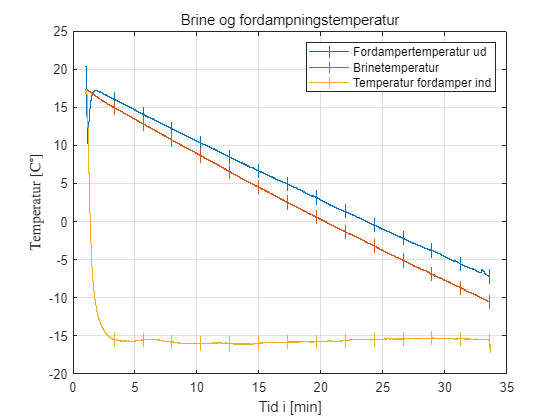


xlin = linspace(1,xs,length(brine_Tffordamp(ind_plot:end)));


lps = length(xlin);

errlin = zeros(1,lps);

fejl = 0.9798;

for i = 1:lps
    if mod(i,500) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end



figure

errorbar(xlin, brine_Tefordamp(ind_plot:end),errlin,"CapSize",0)
hold on
errorbar(xlin, brine_Tbrine(ind_plot:end),errlin,"CapSize",0)
errorbar(xlin, brine_Tffordamp(ind_plot:end),errlin,"CapSize",0)
hold off


title("Brine og fordampningstemperatur","FontWeight","normal")
grid("on")
legend("Fordampertemperatur ud","Brinetemperatur","Temperatur fordamper ind","location","northeast")

xlabel("Tid i [min]")
ylabel("Temperatur $[\mathrm{C}^\circ]$","Interpreter","latex")

exportgraphics(gcf,"FordampBrineTempsBrine.png")

T_komp = find(brine.textdata(1,2:end) == "Temperaturen efter fordamper")

T_komp = 6


T_fordamp = find(brine.textdata(1,2:end) == "Temperatur efter EPV")

T_fordamp = 9

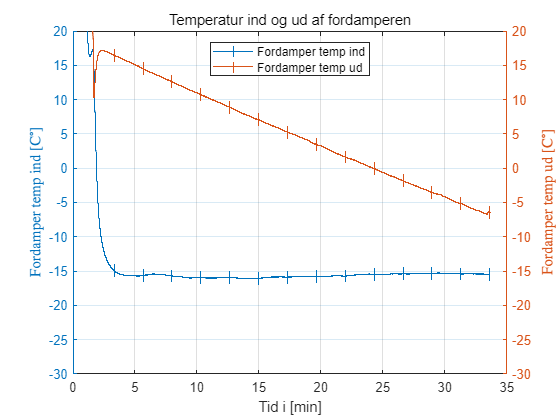


T1 = brine.data(ind:end-ind-9-100, T_komp);
T4 = brine.data(ind:end-ind-9-100, T_fordamp);

errlin = zeros(1,lps);

fejl = 0.9798;

for i = 1:lps
    if mod(i,500) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end


figure

yyaxis left
errorbar(xlin, T4,errlin,"CapSize",0)
ylabel("Fordamper temp ind [C$^\circ$]", "Interpreter","latex")

ylim([-30,20])

yyaxis right
errorbar(xlin, T1,errlin,"CapSize",0)
ylabel("Fordamper temp ud [C$^\circ$]", "Interpreter","latex")

ylim([-30,20])

grid("on")
legend("Fordamper temp ind","Fordamper temp ud","Location","north")
title("Temperatur ind og ud af fordamperen","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf,"FordampTempsBrine.png")

## Phi

R = 2.023e-5 + 0.00391 + 7.676e-5;

phi = -(brine_Tffordamp(ind_plot:end) - brine_Tbrine(ind_plot:end))/R;

errlin = zeros(1,lps);

tpdf = brine_Tffordamp(ind_plot:end) - brine_Tbrine(ind_plot:end);

fejl = -(max(tpdf))/R;

for i = 1:lps
    if mod(i,500) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end

phimin = 1249.36;

min(brine_Tbrine(ind_plot:end))

ans = -10.6185

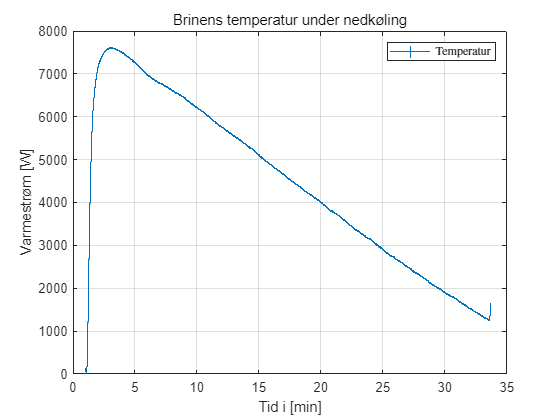


figure

%yyaxis left
errorbar(xlin, phi,errlin,"CapSize",0)
ylabel("Varmestrøm [W]")

%yyaxis right
% errorbar(xlin, brine_Tbrine(ind_plot:end),errlin,"CapSize",0)
% ylabel("Temperatur $[\mathrm{C}^\circ]$","Interpreter","latex")

title("Brinens temperatur under nedkøling","FontWeight","normal")
grid("on")
xlabel("Tid i [min]")


legend("Temperatur","Interpreter","latex")

exportgraphics(gcf,"VarmestromBrine.png")

## Tryk

brine_lavtryk = find(brine.textdata(1,2:end) == "Tryk lav")

brine_lavtryk = 13

brine_hojtryk = find(brine.textdata(1,2:end) == "Tryk høj")

brine_hojtryk = 12

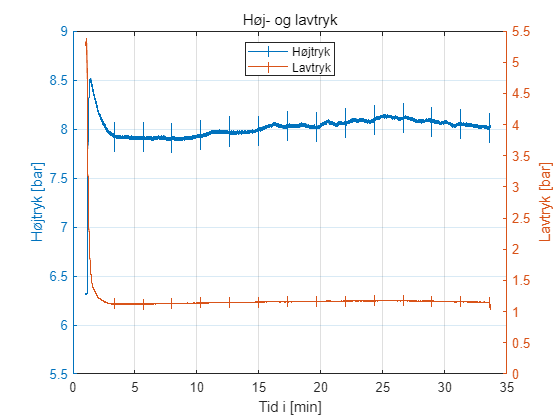


brine_lavtryk = brine.data(ind_plot:end-19, brine_lavtryk) + 1;
brine_hojtryk = brine.data(ind_plot:end-19, brine_hojtryk) + 1;

errlin_hoj = zeros(1,lps);
errlin_lav = zeros(1,lps);

fejlhoj = 0.008*20;
fejllav = 0.008*12;

for i = 1:lps
    if mod(i,500) == 0
        errlin_hoj(i) = fejlhoj;
        errlin_lav(i) = fejllav;
    else
        errlin_hoj(i) = 0;
        errlin_lav(i) = 0;
    end
    
end

figure

yyaxis left
errorbar(xlin, brine_hojtryk,errlin_hoj,"CapSize",0)
ylabel("Højtryk [bar]")
ylim([5.5,9])

yyaxis right
errorbar(xlin, brine_lavtryk,errlin_lav,"CapSize",0)
ylabel("Lavtryk [bar]")

ylim([0,5.5])

grid("on")
legend("Højtryk","Lavtryk","Location","north")
title("Høj- og lavtryk","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf,"HojLavTrykBrine.png")